# Hexapod - Lidar

Navigate through a maze with smooth terrain.

Position is known from GPS, while lidar generates a occupancy map to navigate through.

Use hexapod.lidarPlanner class.

## Create maze

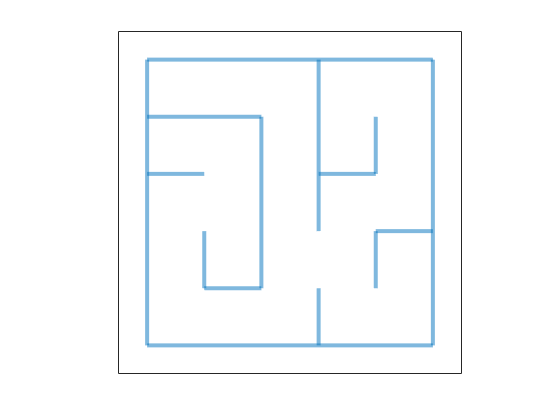

branching = 6;
mazeCreator(branching,'middle',false,false);
pad = 24;
maze = getframe(gca).cdata(pad:end-pad,pad:end-pad,1);

maze = maze(1:2:end, 1:2:end);
size(maze)

ans =    148   149


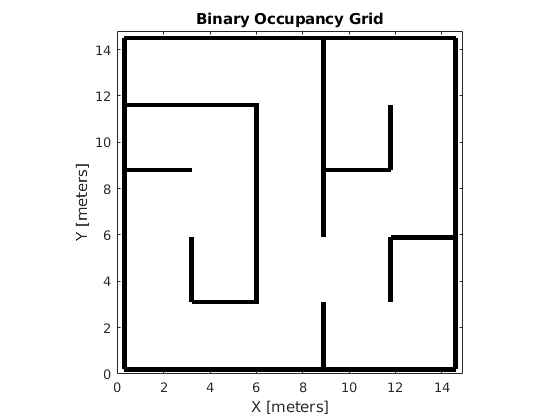

%turn maze into occupancy grid
maze = imbinarize(maze);
maze = imcomplement(maze);
mazeRes = 10;
map = binaryOccupancyMap(maze, mazeRes);
%map.inflate(1/10);
map.show();

## Run simulation

goalPose = [13 13 0];
startPose = [2 2 0];
Ts = 0.1;
Tf = 140;
open_system('lidar');
simout = sim('lidar', [0 Tf]);

 

waypoints = simout.yout{1}.Values.Data;
waypoints = squeeze(waypoints)';
size(waypoints)

ans =         1401           2


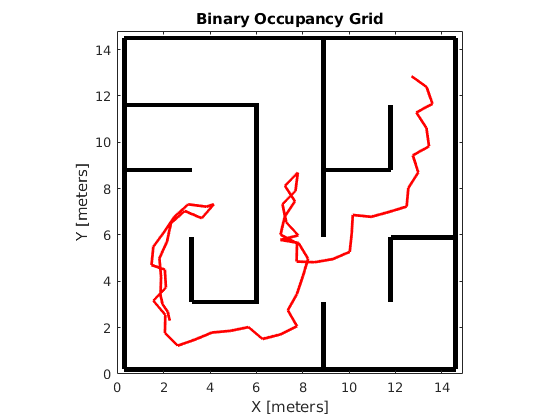

figure
map.show;
hold on;
plot(waypoints(:,1), waypoints(:,2),'r-','LineWidth',2);

occMaps = simout.yout{2}.Values.Data;
size(occMaps)

ans =          148         149        1401


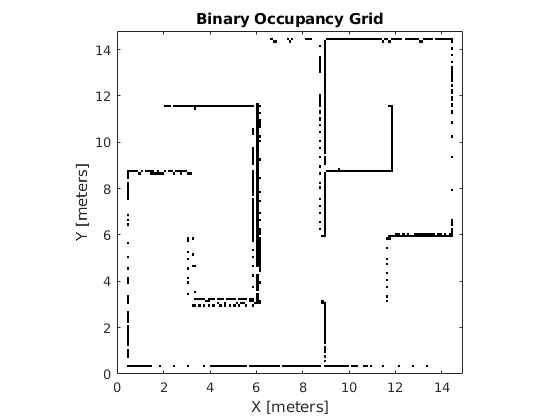

pose =      2     2     0


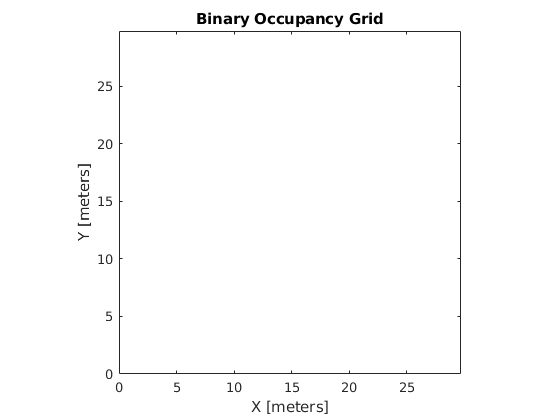

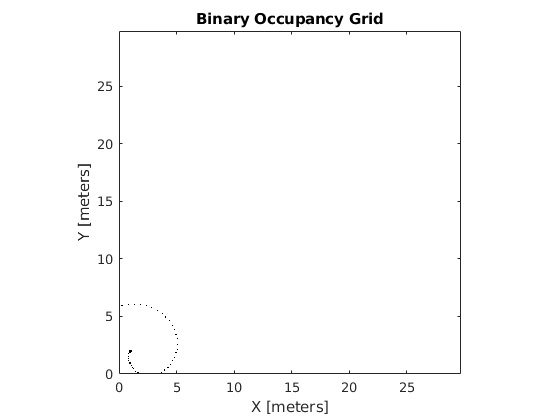

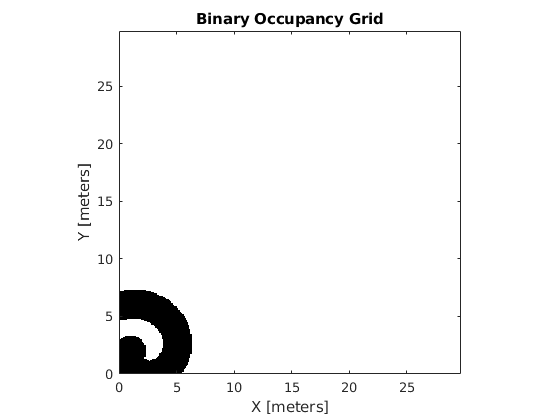

wps =      2     2
     3     3
     4     4
     5     5
     6     6
     7     7
     8     8
     9     9
    10    10
    11    11


lastMap = binaryOccupancyMap(occMaps(:,:,size(occMaps, 3)), mazeRes);
lastMap.show;